# Power-Split HEV with Speed Tracking

Power-split HEV model with speed tracking is a hybrid electric vehicle model with a simple rule-based controller which traces the vehicle speed reference.

- [Open](matlab:open('PowerSplitHEV_params.m')) the script defining plant model parameters

- [Open](matlab:open('HEVPowerSplitControl_params.m')) the script defining controller/driver parameters

By default, the following drive patterns/cycles are available:

- Acceleration deceleration pattern

- Simple drive pattern

- FTP-75 drive cycle

Hyperlinks below open a Live Script demonstrating a workflow to open the model, load inputs to workspace, run simulation, and visualize simulation result. You can also use other drive cycles in the Drive Cycle Source block under "Controller & Environment" > "Driving Pattern" subsystem.

## Acceleration and Deceleration Pattern

- [Open](matlab:open('PowerSplitHEV_SpeedTracking_accelerate_decelerate_kph.mlx')) script

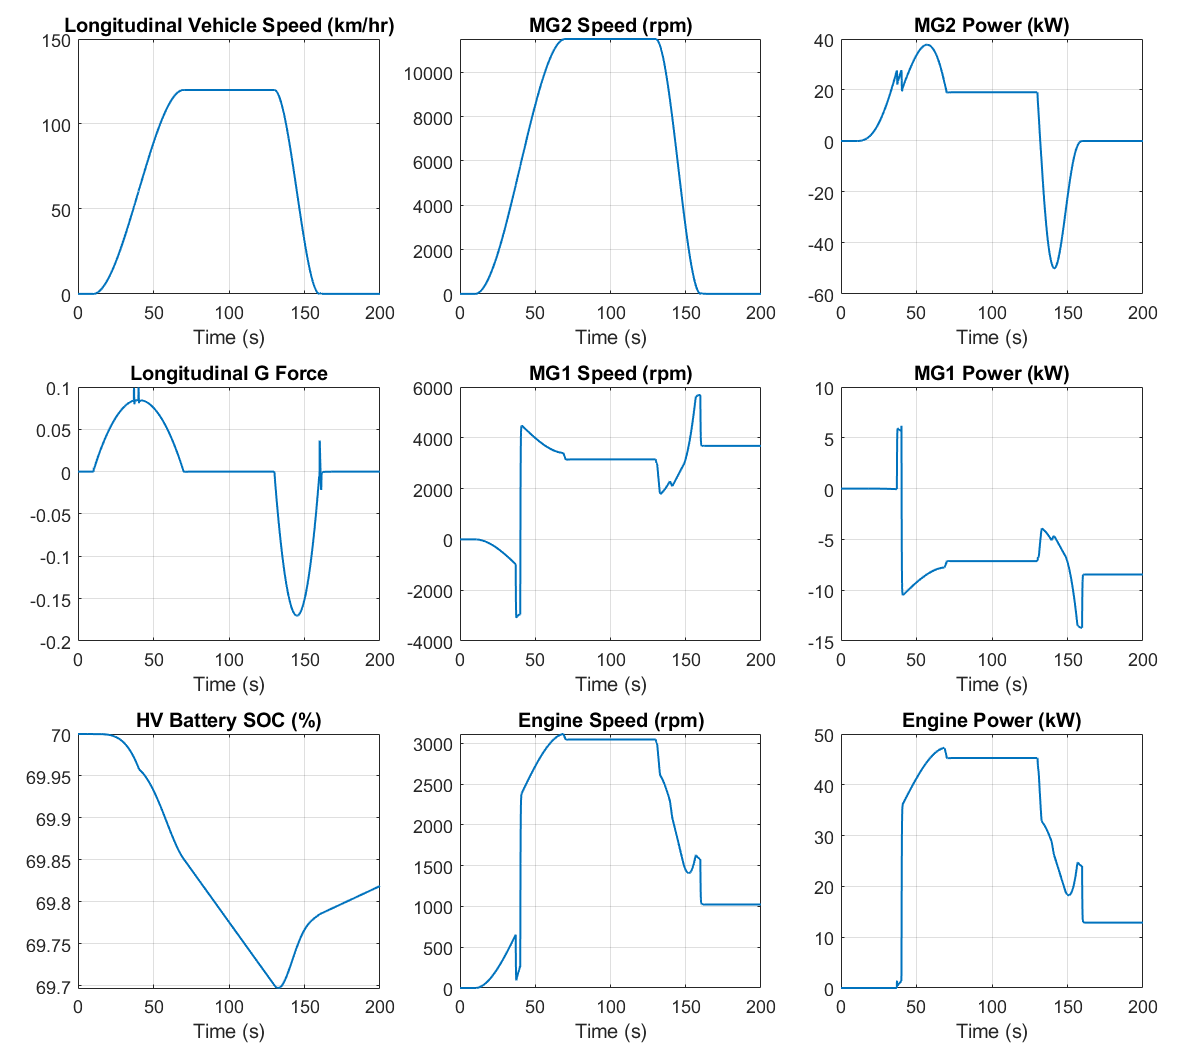

runSimulationAndMakePlots("accelerate_decelerate_kph")

## Simple Drive Pattern

- [Open](matlab:open('PowerSplitHEV_SpeedTracking_simple_drive_pattern.mlx')) script

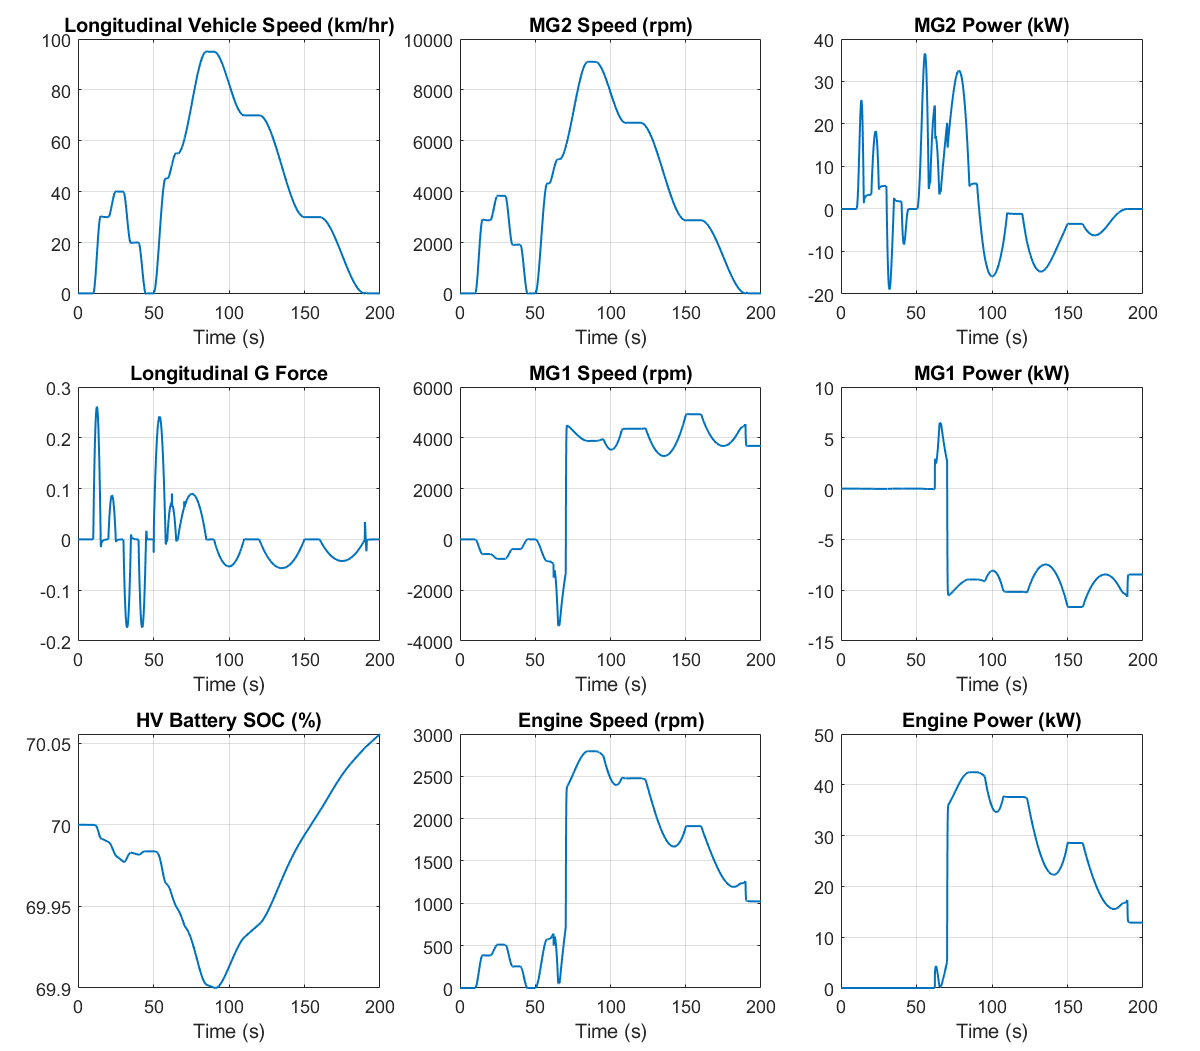

runSimulationAndMakePlots("simple_drive_pattern")

## FTP-75 Drive Cycle

- [Open](matlab:open('PowerSplitHEV_SpeedTracking_ftp75.mlx')) script

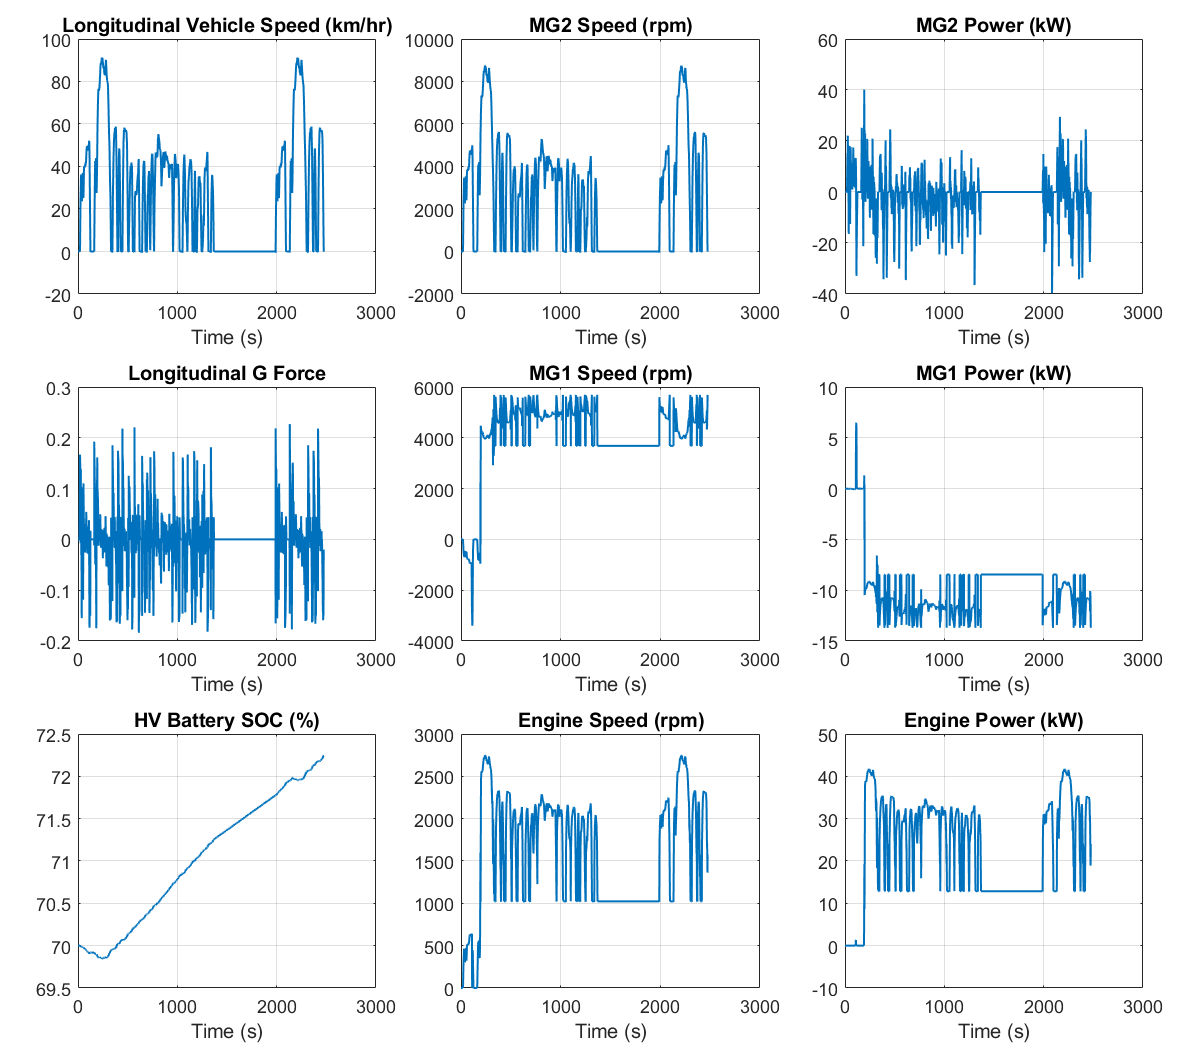

runSimulationAndMakePlots("ftp75_mph")

function runSimulationAndMakePlots(input_pattern)
arguments
  input_pattern {mustBeTextScalar}
end

mdl = "PowerSplitHEV_SpeedTracking";

% Load model
if not(bdIsLoaded(mdl))
  load_system(mdl);
end

% Load default parameters
PowerSplitHEV_params

% Load external input - vehicle speed reference
[inputSignals_DrivingPattern, inputBus_DrivingPattern, ~, opt1] = ...
  DrivingPatternBasic_inputs( "PlotSpeedOnly",true, "InputPattern", input_pattern );

drivingPattern.useFromWorkspace_tf = opt1.useFromWorkspace;

% Load external input - road grade
[inputSignals_RoadGrade, inputBus_RoadGrade, opt2] = ...
  DriverAndEnvironment_road_grade_pattern( "InputPattern", "flat" );

% Simulation time
t_end = max(opt1.t_end, opt2.t_end);

dt = 0;  % 0 for variable-step solver

in = Simulink.SimulationInput(mdl);
in = setModelParameter(in, 'StopTime',num2str(t_end));
in = setVariable(in, 'dt', dt);
in = setVariable(in, 'drivingPattern.useFromWorkspace_tf', drivingPattern.useFromWorkspace_tf);

in = setVariable(in, 'inputSignals_DrivingPattern', inputSignals_DrivingPattern);
in = setVariable(in, 'inputBus_DrivingPattern', inputBus_DrivingPattern);
in = setVariable(in, 'inputSignals_RoadGrade', inputSignals_RoadGrade);
in = setVariable(in, 'inputBus_RoadGrade', inputBus_RoadGrade);

% Run simulation
out = sim(in);

fig = figure;
PowerSplitHEV_SpeedTracking_plot_result_compact( "Dataset",out.logsout, "PlotParent",fig );
end  % function

*Copyright 2021-2022 The MathWorks, Inc.*